# Fordamper

clc; clear all;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");

middel = "R134a";
h1 = 389428;
h4 = 241463; % I J/kg
p4 = 1.330*1e5; % I pascal

hlin = linspace(h4,h1,100);
plin = linspace(p4,p4,100);

qmr = 0.00849 *u.kg/u.s;

A_i = (0.00792/2)^2*pi

A_i = 4.9265e-05

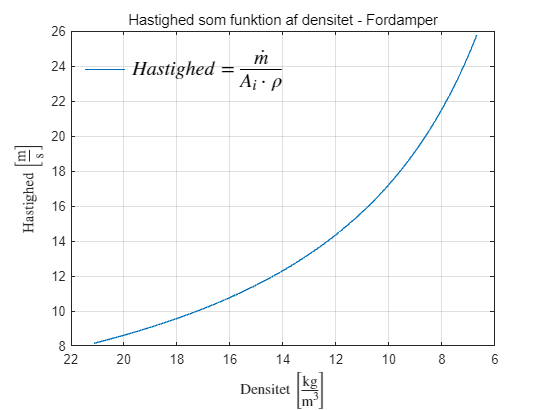



% Fordamper densitet og hastigheder

Ds = zeros(1, length(hlin));

for i = 1:length(hlin)
    Ds(i) = CP.PropsSI("D","H",hlin(i),"P",plin(i), middel);
end

vs_fordamp = zeros(1,length(hlin));

for h = 1:length(hlin)
    vs_fordamp(h) = separateUnits(qmr)/(Ds(h)*A_i);
end

figure
plot(Ds, vs_fordamp)

grid("on")
title("Hastighed som funktion af densitet - Fordamper","FontWeight","normal")
xlabel("Densitet $\left[\frac{\mathrm{kg}}{\mathrm{m^3}}\right]$", "Interpreter","latex")
ylabel("Hastighed $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$", "Interpreter","latex")

legend("$Hastighed = \frac{\dot{m}}{A_i \cdot\rho}$","Interpreter","latex","FontSize",15,"Box","off", "Location","northwest")

set(gca, "XDir","reverse")

exportgraphics(gcf, "HastDensFordamp.png")

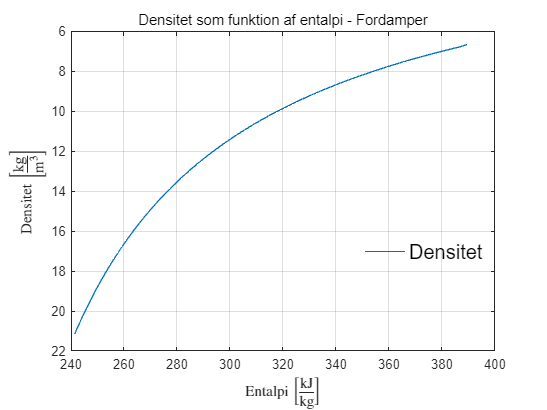


figure
plot(hlin/1e3, Ds)

grid("on")
title("Densitet som funktion af entalpi - Fordamper", "FontWeight","normal")
xlabel("Entalpi $\left[\frac{\mathrm{kJ}}{\mathrm{kg}}\right]$","Interpreter","latex")
ylabel("Densitet $\left[\frac{\mathrm{kg}}{\mathrm{m^3}}\right]$", "Interpreter","latex")

legend("Densitet","location","best","FontSize",15,"box","off")

set(gca, "YDir","reverse")


%
% Ts = zeros(1,length(hlin));
%
% for j = 1:length(hlin)
%     Ts(i) = CP.PropsSI("T","D",Ds(j), "P",plin(j), middel);
%
% end

v_ud_fordamp = max(vs_fordamp)

v_ud_fordamp = 25.7815

rho_ud_fordamp = min(Ds)

rho_ud_fordamp = 6.6844

v_ind_fordamp = min(vs_fordamp)

v_ind_fordamp = 8.1570

rho_ind_fordamp = max(Ds)

rho_ind_fordamp = 21.1269


mean_v = mean(vs_fordamp)

mean_v = 16.9250

mean_rho = mean(Ds)

mean_rho = 11.3025

## Energi i løbet af fordamper

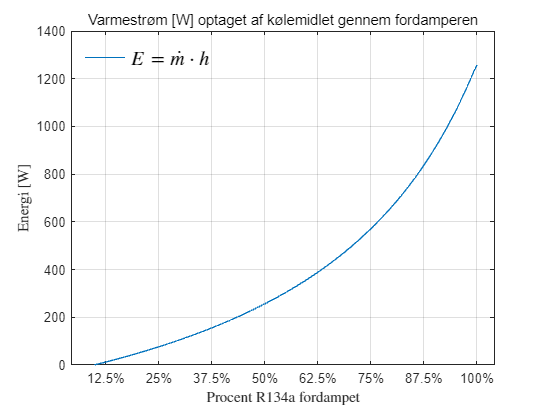

hs_units = (hlin-min(hlin)).*u.J/u.kg;

W_fordamp = vpa(qmr.*hs_units,6);

Wfordamp_plot = separateUnits(W_fordamp);

figure
plot(Ds,Wfordamp_plot)
title("Varmestrøm [W] optaget af kølemidlet gennem fordamperen","FontWeight","normal")
grid("on")
ylabel("Energi [W]","Interpreter","latex")
xlabel("Procent R134a fordampet", "Interpreter","latex")

xticks(min(Ds):2:max(Ds))

set(gca, "XDir","reverse")


xticklabels(fliplr(["0%" "12.5%" "25%" "37.5%" "50%" "62.5%" "75%" "87.5%" "100%"]))


legend("$E = \dot{m} \cdot h$","Interpreter","latex","FontSize",15,"Box","off","location","northwest")

exportgraphics(gcf, "EnergiDensFordamp.png")



kond_ror = 6.7*u.m; % meter
vs_units = vpa(mean(vs_fordamp)*u.m/u.s,4)

$$vs\_units = 16.92\,\frac{m}{s}$$


t_i_ror = vpa(kond_ror/vs_units,4)

$$t\_i\_ror = 0.3959\,s$$



fordamp_Wdiff = max(Wfordamp_plot) - min(Wfordamp_plot);



fordamp_W_eff = fordamp_Wdiff*(u.J/u.s);%*t_i_ror;
fordamp_W_eff = vpa(unitConvert(fordamp_W_eff,"SI","Derived"),7)

$$fordamp\_W\_eff = 1256.223\,W$$






fordamp_W_eff*t_i_ror

$$ans = 497.29423591982070632165360643591\,W\,s$$


% 500 watt
% Hvor meget energi er der i saltvandsblandingen? Det er nødvendigt at
% vide, for at finde ud af hvor lang tid det vil tage at køle ned
% Modstande skal inkluderes


# Beregninger til brine

CPvand = vpa(CP.PropsSI("C","T",293.15,"Q",0,"Water"),3)*u.J/(u.kg*u.K)

$$CPvand = 4184.3605144023895263671875\,\frac{J}{K\,\mathrm{kg}}$$

CPsalt = 0.853 * u.J/(u.g*u.K);
CPsalt = unitConvert(CPsalt,u.J/(u.kg*u.K))

$$CPsalt = 853\,\frac{J}{K\,\mathrm{kg}}$$


CPbrine = 0.75*CPvand + 0.25*CPsalt

$$CPbrine = 3351.520385801792144775390625\,\frac{J}{K\,\mathrm{kg}}$$


dT = 27*u.K;
mbrine = 20*u.kg;

Ebrine = vpa(unitConvert(mbrine*dT*CPbrine,u.kJ),6)

$$Ebrine = 1809.82\,\mathrm{kJ}$$


vpa(unitConvert(Ebrine/fordamp_W_eff,u.min),5)

$$ans = 24.011\,\min$$



D_brine = CP.PropsSI("D","T",293.15,"P",plin(1),middel)*u.kg/u.m^3;
dyn_vis_brine = CP.PropsSI("V","T",293.15,"P",plin(1),middel)*u.Pa*u.s;
kin_vis_brine = vpa(unitConvert(dyn_vis_brine/D_brine,"SI","Derived"),9)

$$kin\_vis\_brine = 0.00000202537843\,\frac{m^{2}}{s}$$

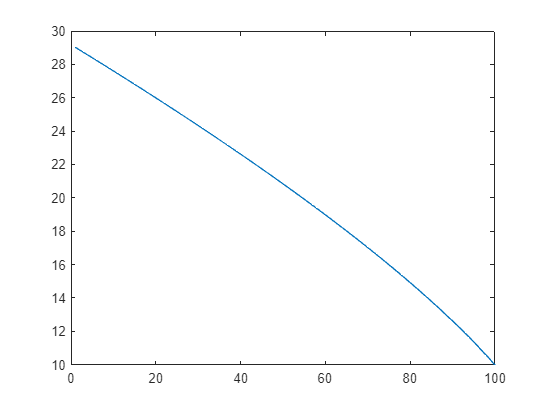

figure

t_fi = linspace(82.25, 35);    % Kølemiddel temp ind
t_fu = 35;    % Kølemiddel temp ud

t_lu = 27.54;    % Luft temp ud
t_li = 22;    % Luft temp ind

T_LM = ((t_fi - t_lu)-(t_fu - t_li))./log((t_fi - t_lu)./(t_fu - t_li));


plot(T_LM)


%set(gca, "XDir","reverse")





# Vægtemperaturer ved rør

middel = "R134a";
h1 = 389428;
h4 = 241463; % I J/kg
p4 = 1.330*1e5; % I pascal

hlin = linspace(h4,h1,100);
plin = linspace(p4,p4,100);


di = unitConvert(7.6*u.mm,"SI");
du = unitConvert(8*u.mm,"SI");
alpha_middel = 1810.45 *u.W/(u.m^2*u.K);
alpha_brine = 1507 * u.W/(u.m^2*u.K);
lambda_kobber = 372 * u.W/(u.m*u.K);

%U_u = vpa(1/(1/(alpha_brine+alpha_middel) + log(du/di)/(2*pi*lambda_kobber) * pi*du))

U_u = vpa(1/(1/(alpha_middel) * du/di + du/(2*lambda_kobber)*log(du/di) + 1/alpha_brine),5) % ligning 9.62

$$U\_u = 802.86\,\frac{W}{K\,m^{2}}$$


L = 6.7*u.m;
Au = du*pi;
tfi = -20*u.K;
tfu = 10*u.K;
phi = vpa(U_u*Au*(tfi - tfu),6)

$$phi = -605.345\,\frac{W}{m}$$

phi_L = phi*L

$$phi\_L = -4055.8113697205772041343152523041\,W$$


tv_ror = vpa(tfi - phi/((alpha_middel+alpha_brine)*Au),5)

$$tv\_ror = -12.74\,K$$


t_fi = -20;    % Kølemiddel temp ind
t_fu = -15;    % Kølemiddel temp ud

t_lu = -10;    % Luft temp ud
t_li = 20;    % Luft temp ind

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li))*u.K;
T_LM = vpa(T_LM, 4)

$$T\_LM = -19.96\,K$$


vpa(U_u*Au*L*T_LM,5)

$$ans = -2697.9\,W$$




% Herunder er koden til iteration af varmeovergangstallet

%nu = 0.000001511; %m^2 / s
tv_ror = double(separateUnits(tv_ror)); % første gæt 12
D_fordamp = CP.PropsSI("D","T",273.15 - tv_ror,"P",plin(1),middel)*u.kg/u.m^3;
dyn_vis_eta = CP.PropsSI("V","T",273.15 - tv_ror,"P",plin(1),middel)*u.Pa*u.s;
kin_vis_nu = vpa(unitConvert(dyn_vis_eta/D_fordamp,"SI","Derived"),4);

qmr = 0.00849*u.kg/u.s;

d_1 = vpa(di,3); % m %indre diameter af kobber rør

g = 9.82 * u.m/u.s^2;

lambda_1 = CP.PropsSI("L","T",273.15 - tv_ror,"P",plin(1),middel)*u.W/(u.m*u.K);

r_fordamp = 211.2 * 1000 * u.J/u.kg;%m * l_fd



Re_1 = vpa(unitConvert(qmr * d_1 / (pi/4 * d_1^2 * dyn_vis_eta),"SI","Derived"),3);

K_f = vpa(unitConvert(r_fordamp / (L * g),"SI"),3);

NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40;

alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,7)

$$alpha\_1\_ = 3718.218\,\frac{W}{K\,m^{2}}$$

# Vægtemperaturer ved glas

CPvand = vpa(CP.PropsSI("C","T",293.15,"Q",0,"Water"),3)*u.J/(u.kg*u.K)

$$CPvand = 4184.3605144023895263671875\,\frac{J}{K\,\mathrm{kg}}$$

CPsalt = 0.853 * u.J/(u.g*u.K);
CPsalt = unitConvert(CPsalt,u.J/(u.kg*u.K))

$$CPsalt = 853\,\frac{J}{K\,\mathrm{kg}}$$


CPbrine = 0.75*CPvand + 0.25*CPsalt;

dT = 30*u.K;
mbrine = 20*u.kg;

Ebrine = vpa(unitConvert(mbrine*dT*CPbrine,u.kJ),6)

$$Ebrine = 2010.91\,\mathrm{kJ}$$


unitConvert(Ebrine/fordamp_W_eff,u.min)

$$ans = 26.679345832642799979356718369299\,\min$$


di = 0.046*2*u.m;
du = 0.0485*2*u.m;
alpha_slush = 1082 *u.W/(u.m^2*u.K);
alpha_brine = 1507 * u.W/(u.m^2*u.K);
lambda_glas = 1.15 * u.W/(u.m*u.K);


U_u_ud = vpa(1/(1/(alpha_slush) * du/di + du/(2*lambda_glas)*log(du/di) + 1/alpha_brine),5) % ligning 9.62

$$U\_u\_ud = 258.4\,\frac{W}{K\,m^{2}}$$


L = 15*u.cm;
Au = du*pi;
t_brine = -10*u.K;
t_slush = -2*u.K;
phi = vpa(U_u_ud*Au*(t_brine - t_slush),6);
phi_L = vpa(unitConvert(phi*L,"SI","Derived"),3)

$$phi\_L = -94.5\,W$$


tv_glas_ud = vpa(t_brine - phi/((alpha_slush+alpha_brine)*Au),5)

$$tv\_glas\_ud = -9.2015\,K$$

U_u_ind = vpa(1/(1/(alpha_brine) * di/du + di/(2*lambda_glas)*log(du/di) + 1/alpha_slush),5) % ligning 9.62

$$U\_u\_ind = 272.44\,\frac{W}{K\,m^{2}}$$


L = 15*u.cm;
Ai = di*pi;
t_brine = -10*u.K;
t_slush = -2*u.K;
phi = vpa(U_u_ind*Ai*(t_brine - t_slush),6);
phi_L = vpa(unitConvert(phi*L,"SI","Derived"),3)

$$phi\_L = -94.5\,W$$


phi_overfort = vpa(unitConvert((tv_glas_ud-(-2*u.K))/(0.04883*u.K/u.W),"SI", "Derived"), 5)

$$phi\_overfort = -147.48\,W$$


tv_glas_ind = vpa(t_slush - 163.83*u.W/unitConvert(Ai,"SI")/((alpha_slush+alpha_brine)*Ai),5)

$$tv\_glas\_ind = -2.7575\,K$$



phi_overfort = alpha_slush*Ai*L*(tv_glas_ind - t_slush);
phi_overfort = vpa(unitConvert(phi_overfort,"SI", "Derived"), 5)

$$phi\_overfort = -35.534\,W$$

t_fi = -10;    % Kølemiddel temp ind
t_fu = -10;    % Kølemiddel temp ud

t_lu = -2;    % Luft temp ud
t_li = 7;    % Luft temp ind

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li))*u.K;
T_LM = vpa(T_LM, 4)

$$T\_LM = -11.94\,K$$


hmm = vpa(U_u_ind*Ai*L*T_LM,5);
hmm = unitConvert(hmm,"SI","Derived")

$$hmm = -141.02925488812848925590515136719\,W$$

## Der måles lige efter ekspansionsventilen

middel = "air";
g = 9.82*u.m/u.s^2;
tfilm = (22+20)/2;

cp_air = vpa(CP.PropsSI("C","T",273.15 + tfilm,"P", 101350, middel),3)*u.J/(u.kg*u.K)

$$cp\_air = 1006.17567980289459228515625\,\frac{J}{K\,\mathrm{kg}}$$

eta_air = CP.PropsSI("V","T",273.15 + tfilm,"P", 101350, middel)*u.Pa*u.s;
lambda_air = CP.PropsSI("L","T",273.15 + tfilm,"P", 101350, middel)*u.W/(u.m*u.K);
nu_air = vpa(unitConvert(dyn_vis_eta/D_fordamp,"SI","Derived"),4);

beta_air = 3.419*10^(-3)/u.K;

t_guess = -10;
dt = (t_guess - (-20))*u.K;

L = du*pi;

Pr_air = eta_air*cp_air/lambda_air;
Pr_air = vpa(unitConvert(Pr_air, "SI"), 5)

$$Pr\_air = 0.70782$$


Gr_air = g*L^3*beta_air*dt/(nu_air^2);
Gr_air = vpa(unitConvert(Gr_air, "SI"), 5)

$$Gr\_air = 2.5762e+9$$


Ra_air = Gr_air*Pr_air;
Ra_air = vpa(unitConvert(Ra_air, "SI"), 7)

$$Ra\_air = 1.823478e+9$$



syms alpha

Nu1 = alpha*L/lambda_air;
Nu2 = (0.6 + (0.387*Ra_air^(1/6)/((1+(0.559/Pr_air)^(9/16)^(8/27)))))^2;

eq = Nu1 == Nu2;

alpha_air = solve(eq, alpha)

$$alpha\_air = 4.7851927717036715975628454439248\,\frac{W}{K\,m^{2}}$$

Rkobber = 0.00235;


h1 = 389428;
h4 = 241463; % I J/kg
p4 = 1.330*1e5; % I pascal

hlin = linspace(h4,h1,100);
plin = linspace(p4,p4,100);


di = unitConvert(7.92*u.mm,"SI");
du = unitConvert(8*u.mm,"SI");
alpha_middel = 1470 *u.W/(u.m^2*u.K);
alpha_air = alpha_air;
lambda_kobber = 372 * u.W/(u.m*u.K);

%U_u = vpa(1/(1/(alpha_brine+alpha_middel) + log(du/di)/(2*pi*lambda_kobber) * pi*du))

U_u = vpa(1/(1/(alpha_middel) * du/di + du/(2*lambda_kobber)*log(du/di) + 1/alpha_air),5) % ligning 9.62

$$U\_u = 4.7695\,\frac{W}{K\,m^{2}}$$


L = 6.7*u.m;
Au = du*pi;
tfi = -20*u.K;
tfu = 22*u.K;
phi = vpa(U_u*Au*(tfi - tfu),6)

$$phi = -5.03457\,\frac{W}{m}$$

phi_L = phi*L

$$phi\_L = -33.731643338257572395377792418003\,W$$


tv_ror = vpa(tfi - phi/((alpha_middel+alpha_air)*Au),5)

$$tv\_ror = -19.864\,K$$


% t_fi = -20;    % Kølemiddel temp ind
% t_fu = -15;    % Kølemiddel temp ud
% 
% t_lu = -10;    % Luft temp ud
% t_li = 20;    % Luft temp ind
% 
% T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li))*u.K;
% T_LM = vpa(T_LM, 4)
% 
% vpa(U_u*Au*L*T_LM,5)



% Herunder er koden til iteration af varmeovergangstallet

%nu = 0.000001511; %m^2 / s
tv_ror = double(separateUnits(tv_ror)); % første gæt 12
D_fordamp = CP.PropsSI("D","T",273.15 - tv_ror,"P",plin(1),middel)*u.kg/u.m^3;
dyn_vis_eta = CP.PropsSI("V","T",273.15 - tv_ror,"P",plin(1),middel)*u.Pa*u.s;
kin_vis_nu = vpa(unitConvert(dyn_vis_eta/D_fordamp,"SI","Derived"),4);

qmr = 0.00849*u.kg/u.s;

d_1 = vpa(di,3); % m %indre diameter af kobber rør

g = 9.82 * u.m/u.s^2;

lambda_1 = CP.PropsSI("L","T",273.15 - tv_ror,"P",plin(1),middel)*u.W/(u.m*u.K);

r_fordamp = 211.2 * 1000 * u.J/u.kg;%m * l_fd



Re_1 = vpa(unitConvert(qmr * d_1 / (pi/4 * d_1^2 * dyn_vis_eta),"SI","Derived"),3);

K_f = vpa(unitConvert(r_fordamp / (L * g),"SI"),3);

NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40;

alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,7)

$$alpha\_1\_ = 4917.543\,\frac{W}{K\,m^{2}}$$